### Kinematic Chain Modelling

- Base has two prismatic joints (1 * 1/3 m

- 4 Revolute joints

clear all
close all
clc


### Making a Serial Link Chain

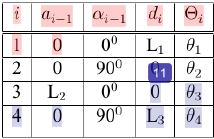

The DH Parameters.

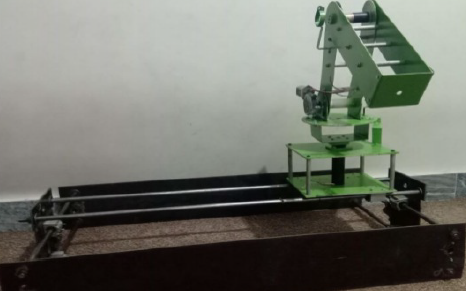

Alpha --> Rotation About X

theta --> Rotation about Z

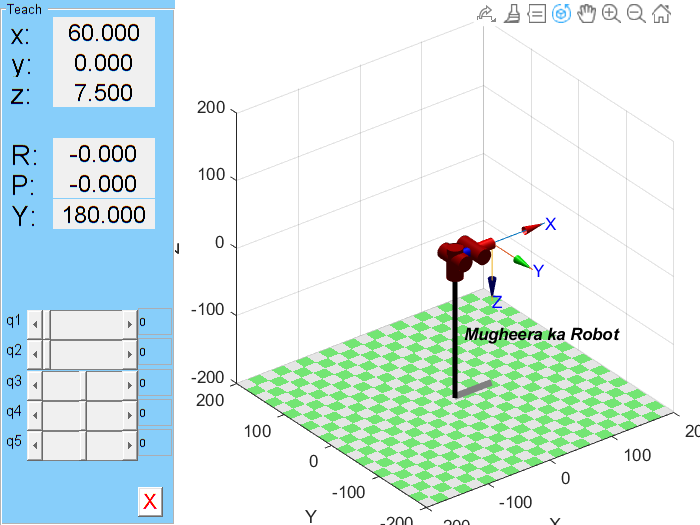

% Define prismatic links

L1 = Link('theta', 0, 'a', 0, 'alpha', pi/2, 'offset', 0, 'qlim', [0 100], 'prismatic');
% L2 = Link('d', 0, 'a', 0, 'alpha', -pi/2, 'offset', 0, 'qlim', [0 0], 'revolute');  % This is the Dummy Link
L2 = Link('theta', pi/2, 'a', 0, 'alpha', -pi/2, 'offset', 0, 'qlim', [0 33.33], 'prismatic');


% L1 = Link('theta', 0, 'a', 0, 'alpha', 0, 'prismatic', 'qlim', [0 100]);
% L2 = Link('theta', 0, 'a', 0, 'alpha', pi/2, 'prismatic', 'qlim', [0 33.33333]);

% Define revolute links
% L3 = Link('revolute', 'd', 7.5, 'a', 0, 'alpha', 0);
L4 = Link('revolute', 'd', 7.5, 'a', 0, 'alpha', pi/2);
L5 = Link('revolute', 'd', 0, 'a', 30.0, 'alpha', 0);
L6 = Link('revolute', 'd', 0, 'a', 30.0, 'alpha', pi/2);


% Create the robot
robot = SerialLink([L1 L2 L4 L5 L6], 'name', 'Mugheera ka Robot');

% Set base and tool (if needed)

robot.base = troty(pi/2); % Example transformation 
% robot.tool = transl(0, 0, 30);   % Example transformation

% Visualize the robot
% robot.plot([0 0 0 0 0 0]);

robot.teach();





% Further analysis and control code...

CHATGPT ki Backchoodi

% clear all; close all; clc
% 
% % Define the first prismatic joint L1 to move along the global X-axis
% % The default orientation is fine, since the Z-axis will be aligned with the X-axis due to the view transformation.
% baseRotX = troty(pi/2); 
% L1 = Link('theta', 0, 'a', 0, 'alpha', 0, 'offset', 0, 'qlim', [0 100], 'prismatic');
% % L2 = Link('d', 0, 'a', 0, 'alpha', -pi/2, 'offset', 0, 'qlim', [0 0], 'revolute');
% 
% 
% 
% 
% % Define the second prismatic joint L2 to move along the global Y-axis
% % Rotate the local frame of L1 by 90 degrees around its X-axis to align L2's Z-axis with the global Y-axis.
% L3 = Link('theta', 0, 'a', 0, 'alpha', 0, 'offset', 0, 'qlim', [0 33.33], 'prismatic');
% 
% % Create the robot model
% robot = SerialLink([L1 L3], 'name', 'My Robot');
% 
% robot.base = troty(pi/2);
% % robot.tool = trotx(-pi/2);
% % Use the 'teach' command to visualize and interact with the robot
% robot.teach();
% % robot.fkine([50,15])
% 
% 
% % Apply a view transformation to look along the global Z-axis onto the XY plane
% view([0 90]);
% 